# MATLAB绘图与图形界面GUI

基本思想：连点成线条

## 1.1二维绘图命令 plot

绘制y = sin(x)

x = linspace(0,2*pi,100);
y = sin(x);

plot(x,y);

## 1.2一幅图形绘制多条曲线

%方式一：利用hold
%hold on 开启图形保持功能，绘制多个图形
%hold off 关闭保存功能
x = linspace(0,2*pi,100);
y1 = sin(x);
y2 = cos(x);

plot(x,y1);
hold on
plot(x,y2);
hold off


%方式二：plot(x,y1,x,y2...)
plot(x,y1,x,y2);

## 1.3添加 坐标轴标签（label）,标题（title）,图例（legend）

x = linspace(0,2*pi,100);
y1 = sin(x);
y2 = cos(x);

plot(x,y1,x,y2);

%添加标签
xlabel("x");
ylabel("y1 = sin(x), y2 = cos(x)");
%添加标题
title("三角函数");
%添加图例
legend("y = sin(x)","y = cos(x)");

## 1.4绘制多附图figure

x = linspace(0,2*pi,100);
y1 = sin(x);
y2 = cos(x);

figure; plot(x,y1);
figure; plot(x,y2);

## 1.5绘制多个子图subplot

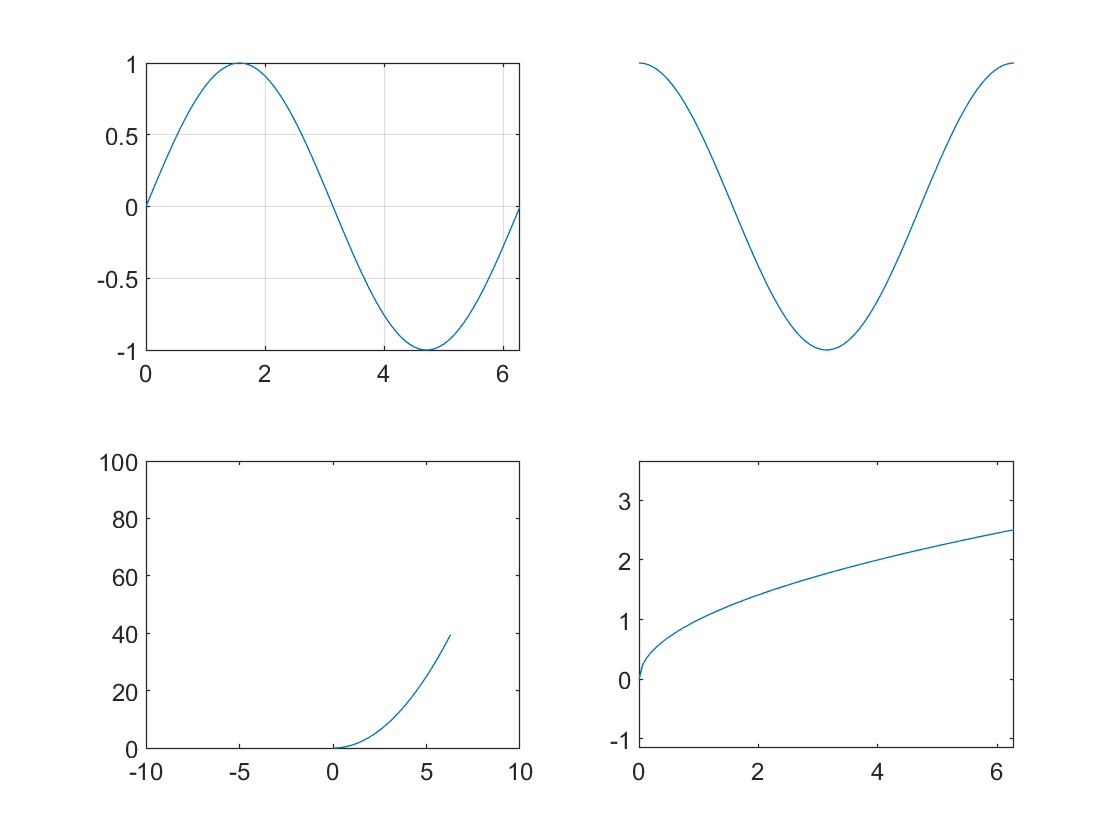

%subplot(m,n,i) 再m行，n列第i个图形
x = linspace(0,2*pi,100);
y1 = sin(x);
y2 = cos(x);
y3 = x.^2;
y4 = x.^0.5;

subplot(2,2,1); plot(x,y1); grid on;
subplot(2,2,2); plot(x,y2); axis off;
subplot(2,2,3); plot(x,y3); axis([-10,10,0,100]);
subplot(2,2,4); plot(x,y4); axis equal;

## 1.6绘图修饰（线形，线宽，

## 颜色，描点类型，网格，坐标刻度）

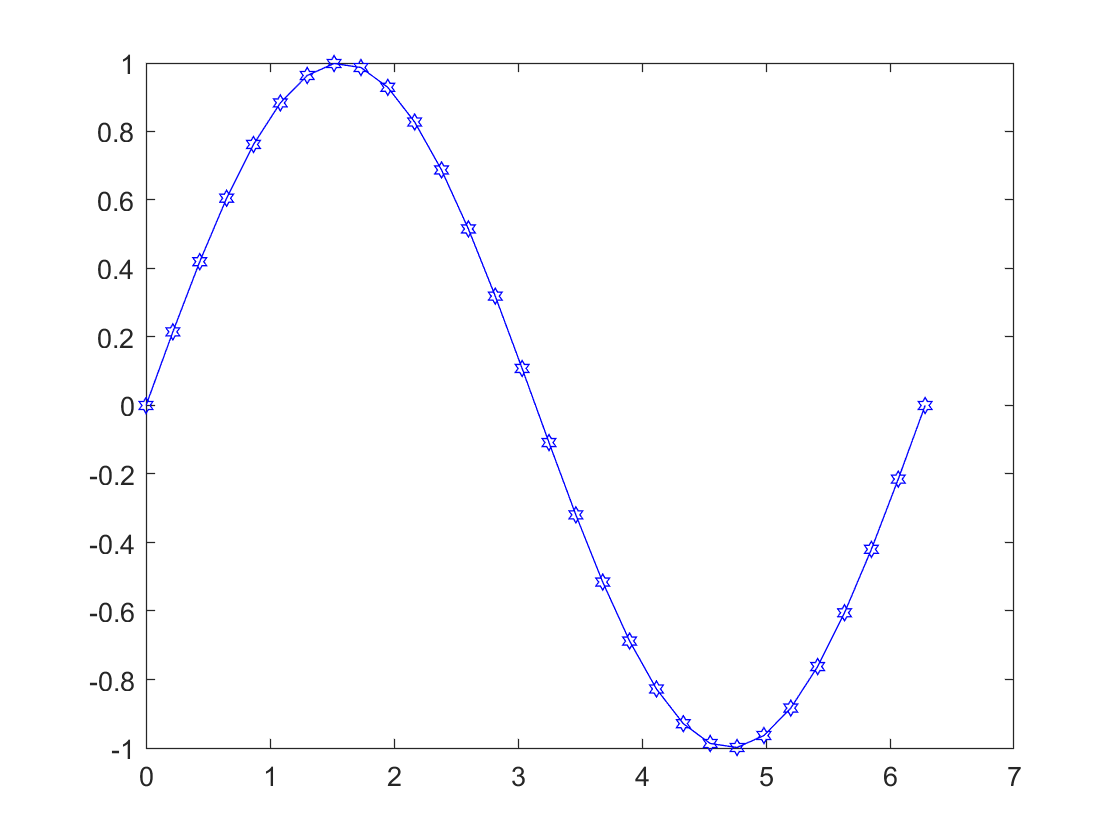

%plot(x,y,'- r o')

%线形 -实线、--虚线、:点线、-.点画线

%描点类型  .点  。圆  x查号 +加号 *星号 
%             < > ^ v（三角形）
%             s方形   d菱形   p五角星  h六角形
%颜色       r g b y黄 w白色 k黑色

x = linspace(0,2*pi,30);
y = sin(x);

plot(x,y,'- b h');

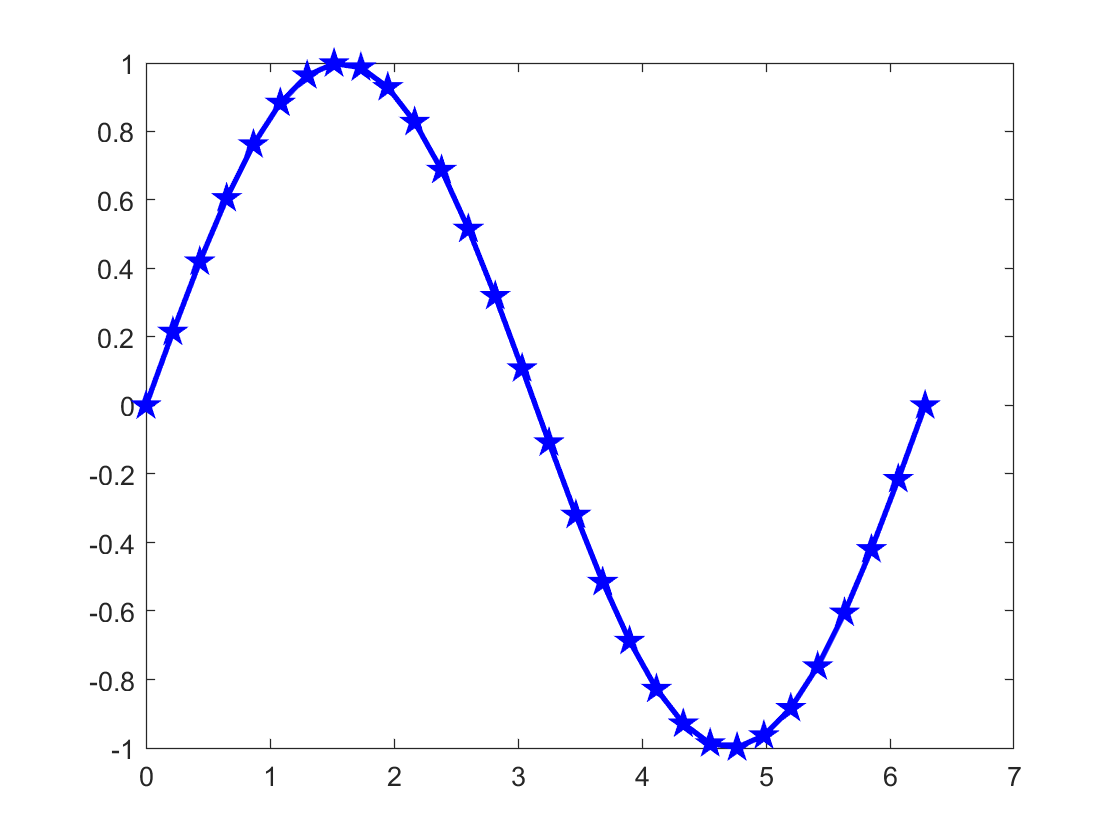


%   'lineWidth',1,     线宽
%   

plot(x,y,'- b p','lineWidth',2);


% grid on 添加网格
% grid off 取消网格
% axis on 显示坐标刻度
% axis off

% axis([xmin,xmax,ymin,ymax]);
% 设置x,y坐标轴的范围